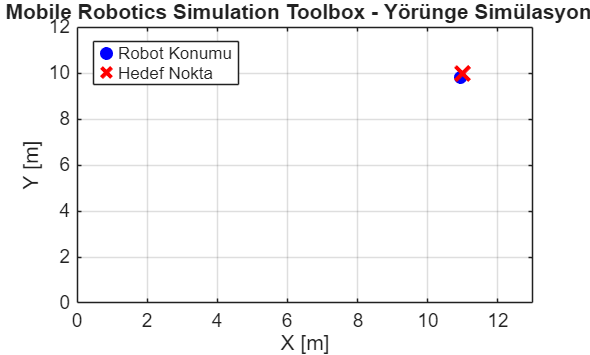

Hedefe başarıyla ulaşıldı!


% Mobile Robotics Simulation Toolbox ile Simülasyonu
clear; clc; close all;

% Ödev Verilerine Göre Robot Parametreleri
R = 0.1; % Tekerlek yarıçapı [m]
L = 0.5; % Dingil açıklığı [m]

% Kinematik Model (Differential Drive)
robot = differentialDriveKinematics("TrackWidth", L, "WheelRadius", R);

% Başlangıç ve Hedef Pozisyonu [x; y; theta]
initPose = [2; 2; 0]; 
goalPose = [11; 10; 0];

% Simülasyon Zaman Adımı ve Pure Pursuit Kontrolcüsü
sampleTime = 0.1;
ctrl = controllerPurePursuit;
ctrl.Waypoints = [initPose(1:2)'; 5 5; goalPose(1:2)'];
ctrl.DesiredLinearVelocity = 1.0;
ctrl.MaxAngularVelocity = 2.0;
ctrl.LookaheadDistance = 0.5;

% Simülasyon Döngüsü
pose = initPose;
figure;
while true
    % Kontrol Komutları (Linear ve Angular Velocity)
    [v, omega] = ctrl(pose);
    
    % Kinematik Güncelleme
    vel = derivative(robot, pose, [v omega]);
    pose = pose + vel * sampleTime;
    
    % Görselleştirme
    plot(pose(1), pose(2), 'bo', 'MarkerFaceColor', 'b'); hold on;
    plot(goalPose(1), goalPose(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
    axis([0 13 0 12]); grid on;
    title('Mobile Robotics Simulation Toolbox - Yörünge Simülasyonu');
    xlabel('X [m]'); ylabel('Y [m]');
    legend('Robot Konumu', 'Hedef Nokta', 'Location', 'NorthWest');
    hold off;
    drawnow;
    
    % Hedefe varış kontrolü
    if norm(pose(1:2) - goalPose(1:2)) < 0.2
        disp('Hedefe başarıyla ulaşıldı!');
        break;
    end
end